# Compare Powers

## Recollect all data

load('../Data/results_BrainBonus2_Laplace.mat')
recollect_data


## basic all power display

figure;
show4images(t,freqs, ...
    mean(mean(erps_powers(:,u,:,:),4),3), ...
    mean(mean(total_powers(:,u,:,:),4),3), ...
    mean(mean(sub_powers(:,u,:,:),4),3), ...
    mean(mean(total_powers(:,u,:,:)-sub_powers(:,u,:,:),4),3), ...
    'BrainBonus2 - P3', ...
    'surf')



regret - power

p_thresh = 0.05;
num_permutations = 1e4;
is_bin = false;
figure;
show_perm_powers(total_powers, 3,1, u, t, p_thresh, num_permutations, is_bin, freqs)

rejoice - power

figure;
show_perm_powers(total_powers, 4,2, u, t, p_thresh, num_permutations, is_bin, freqs)


## Alternative Comparing

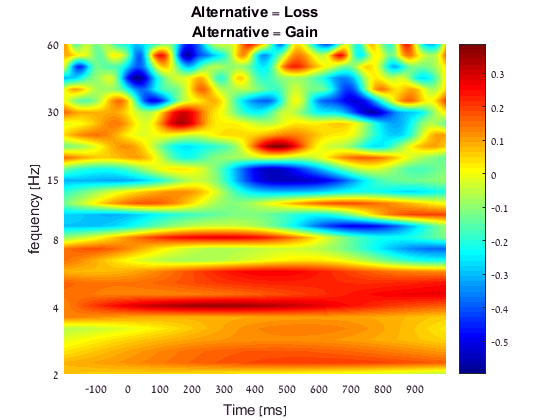

p_thresh = 0.05;
num_permutations = 1e4;
is_bin = false;
figure;
show_perm_powers(total_powers, 3:4,1:2, u, t, p_thresh, num_permutations, is_bin, freqs)
title({'Alternative = Loss','Alternative = Gain'})

figure;
show_perm_powers(total_powers, [1,3], [2,4], u, t, p_thresh, num_permutations, is_bin, freqs)

Cluster 1: time points 1 to 9182, t-sum = -2141.38, p-value = 0.0140986.


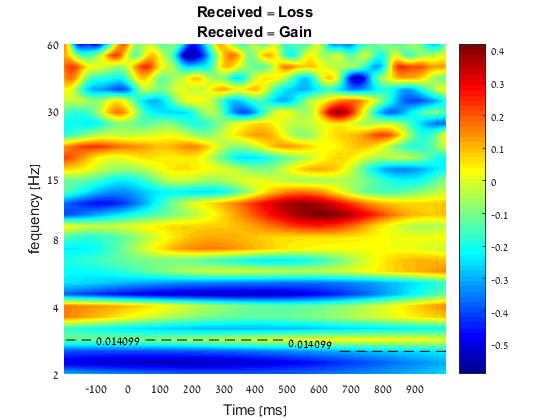

title({'Received = Loss','Received = Gain'})

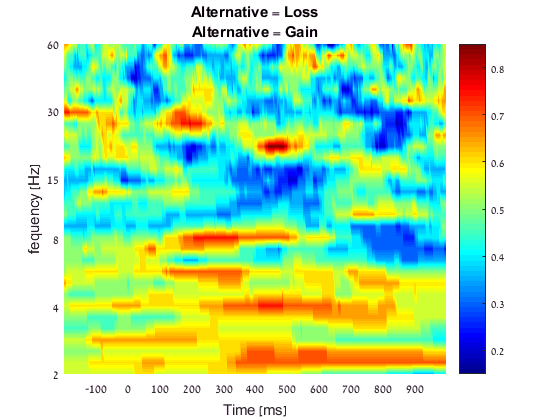

is_bin = true;
figure;
show_perm_powers(total_powers, 3:4,1:2, u, t, p_thresh, num_permutations, is_bin, freqs)
title({'Alternative = Loss','Alternative = Gain'})

figure;
show_perm_powers(total_powers, [1,3], [2,4], u, t, p_thresh, num_permutations, is_bin, freqs)

Cluster 1: time points 1 to 9181, t-sum = -1662.57, p-value = 0.019798.


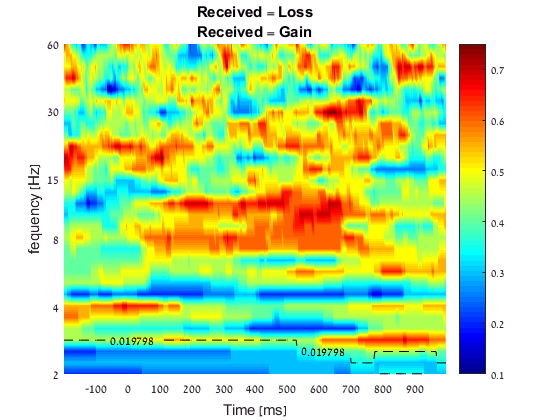

title({'Received = Loss','Received = Gain'})

## Comparing conditional ERPs

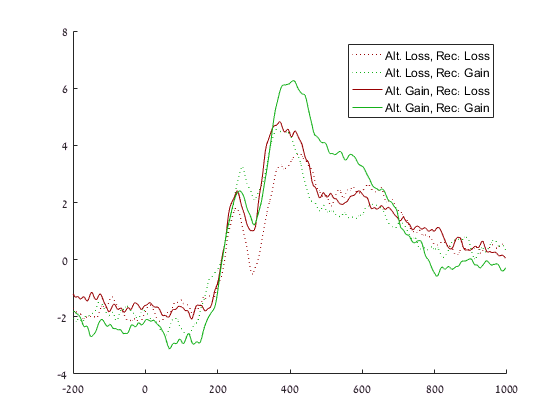

figure
show_4_erp(mean(total_erps,3), u, t)

Cluster 1: time points 132 to 207, t-sum = -277.69, p-value = 9.999e-05.
Cluster 2: time points 297 to 307, t-sum = 25.9517, p-value = 0.440456.
Cluster 3: time points 92 to 99, t-sum = 18.9017, p-value = 0.616338.
Cluster 4: time points 73 to 73, t-sum = 1.75687, p-value = 0.984702.


Cluster 1: time points 140 to 166, t-sum = -76.0178, p-value = 0.039696.
Cluster 2: time points 65 to 92, t-sum = 69.786, p-value = 0.0517948.
Cluster 3: time points 245 to 264, t-sum = 50.2967, p-value = 0.125387.
Cluster 4: time points 118 to 134, t-sum = -42.6125, p-value = 0.184282.
Cluster 5: time points 27 to 32, t-sum = 12.3246, p-value = 0.79602.
Cluster 6: time points 174 to 179, t-sum = -11.9277, p-value = 0.805219.
Cluster 7: time points 183 to 185, t-sum = -5.80484, p-value = 0.937706.
Cluster 8: time points 12 to 14, t-sum = 5.55361, p-value = 0.947805.


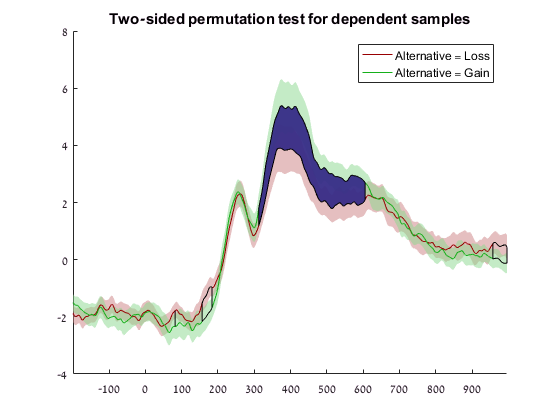

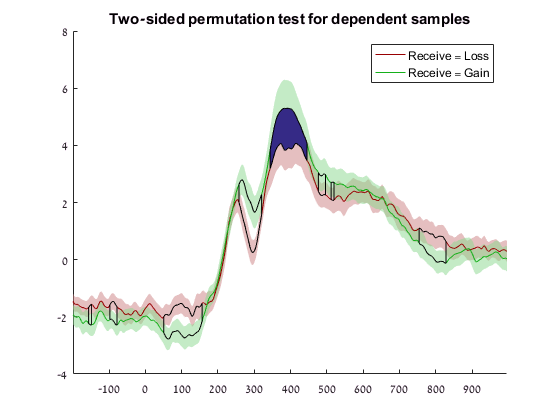



figure;
show_erp_alt_rec(total_erps, u, t)

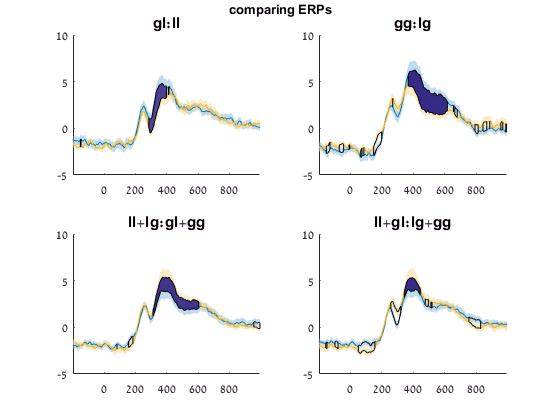

compare_4_conditions(total_erps, u, t, freqs, p_thresh, n , false, 'comparing ERPs')

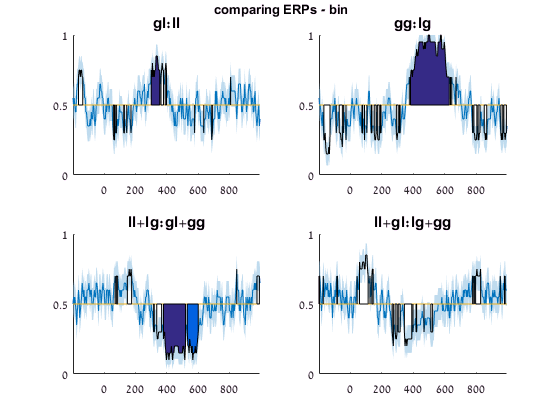

compare_4_conditions(total_erps, u, t, freqs, p_thresh, n , true, 'comparing ERPs - bin')

% show_perm_powers(total_powers, 3:4,1:2, u, t, p_thresh, num_permutations, is_bin, freqs)
% title({'Alternative = Loss','Alternative = Gain'})
% figure;
% show_perm_powers(total_powers, [1,3], [2,4], u, t, p_thresh, num_permutations, is_bin, freqs)
% title({'Received = Loss','Received = Gain'})

## comapring all frequencies!

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_powers(total_powers, 3, 1, u, t, p_thresh, n, false, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_powers(total_powers, 4, 2, u, t, p_thresh, n, false, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_powers(total_powers, 1:2, 3:4, u, t, p_thresh, n, false, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_powers(total_powers, [1 3], [2 4], u, t, p_thresh, n, false, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing mean powers - mean'


figure;
subplot(2,2,1)
show_perm_powers(total_powers, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_powers(total_powers, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_powers(total_powers, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_powers(total_powers, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing mean powers - bin'


p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_powers(sub_powers, 3, 1, u, t, p_thresh, n, false, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_powers(sub_powers, 4, 2, u, t, p_thresh, n, false, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_powers(sub_powers, 1:2, 3:4, u, t, p_thresh, n, false, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_powers(sub_powers, [1 3], [2 4], u, t, p_thresh, n, false, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing mean induced powers - mean'


figure;
subplot(2,2,1)
show_perm_powers(sub_powers, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_powers(sub_powers, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_powers(sub_powers, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_powers(sub_powers, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing mean induced powers - bin'

# Theta

## comparing only Theta powers

theta_power_condition = zeros([length(times), max(condition_positions), length(results)]);
% theta_power_condition2 = theta_power_condition;

freq_min = 4.5;
freq_max = 8;
for subj_ind = 1:length(results)
    theta_power_subject = get_hilbert_power(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    bl_value = mean(mean(theta_power_subject(bl_range, :),2),1);
    
    for cond_ind = 1:size(theta_power_condition,2)
        theta_power_condition(:,cond_ind,subj_ind) = 10 * log10(mean(theta_power_subject(:,results{subj_ind}.condition_positions == cond_ind)./bl_value,2));
%         theta_power_condition2(:,cond_ind,subj_ind) = mean(10 * log10(theta_power_subject(:,results{subj_ind}.condition_positions == cond_ind)./bl_value),2);
    end
end

erp_power_condition = [];
for subj_ind = 1:length(results)
    for cond_ind = 1:size(theta_power_condition,2)
        erp_power_condition(:,cond_ind,subj_ind) = get_hilbert_power(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
    end
end


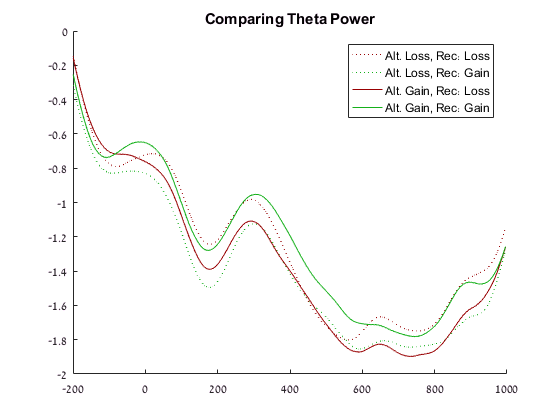

figure
show_4_erp(mean(theta_power_condition,3), u, t)
title('Comparing Theta Power')

No significant clusters found.


Cluster 1: time points 1 to 10, t-sum = 19.2647, p-value = 0.676232.


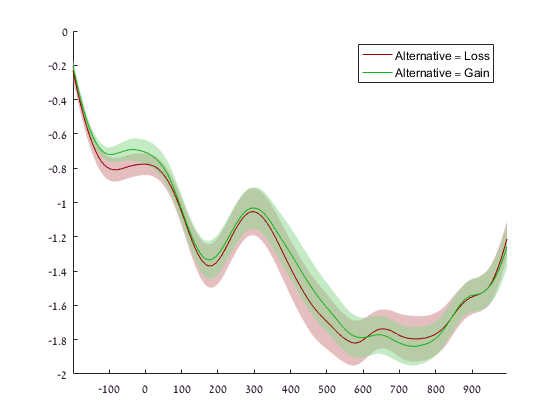

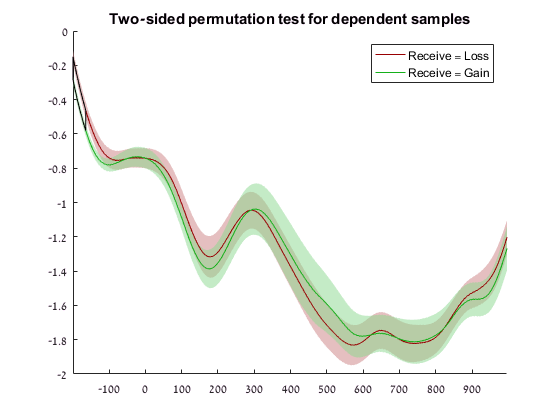


figure;
show_erp_alt_rec(theta_power_condition, u, t)

p_thresh = 0.05;
n = 1e4;
compare_4_conditions(theta_power_condition, u, t, freqs, p_thresh, n, false, sprintf('comparing mean Theta (%.2g-%.2g)- mean', freq_min, freq_max))
compare_4_conditions(theta_power_condition, u, t, freqs, p_thresh, n, true, sprintf('comparing mean Theta (%.2g-%.2g)- bin', freq_min, freq_max))
% compare_4_conditions(theta_power_condition2, u, t, freqs, p_thresh, n, false, sprintf('comparing log-mean Theta (%.2g-%.2g)- mean', freq_min, freq_max))
% compare_4_conditions(theta_power_condition2, u, t, freqs, p_thresh, n, true, sprintf('comparing log-mean Theta (%.2g-%.2g)- bin', freq_min, freq_max))
compare_4_conditions(erp_power_condition, u, t, freqs, p_thresh, n, false, sprintf('comparing ERP Theta (%.2g-%.2g)- mean', freq_min, freq_max))
compare_4_conditions(erp_power_condition, u, t, freqs, p_thresh, n, true, sprintf('comparing ERP Theta (%.2g-%.2g)- bin', freq_min, freq_max))

## using wavelets

figure;
freq_ind = 11;
freqs(freq_ind)

ans = 6.4622

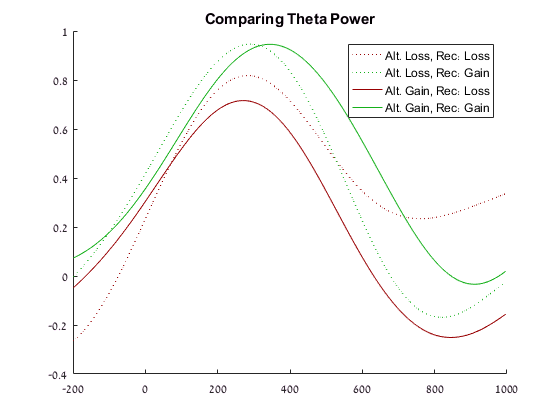

show_4_erp(mean(squeeze(total_powers(freq_ind,:,:,:)),3), u, t)
title('Comparing Theta Power')

No significant clusters found.


Cluster 1: time points 164 to 181, t-sum = -31.6694, p-value = 0.333267.


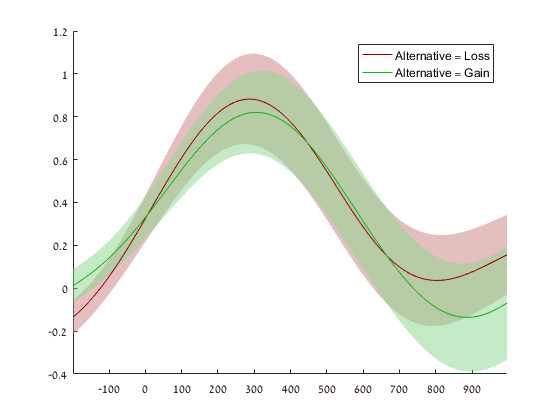

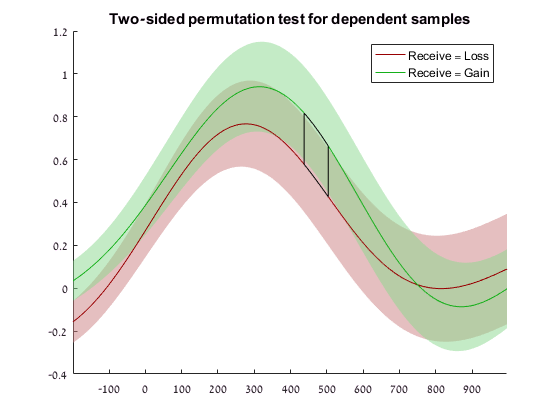


figure;
show_erp_alt_rec(squeeze(total_powers(freq_ind,:,:,:)), u, t)

figure;
freq_ind = 8;
freqs(freq_ind)

ans = 4.5454

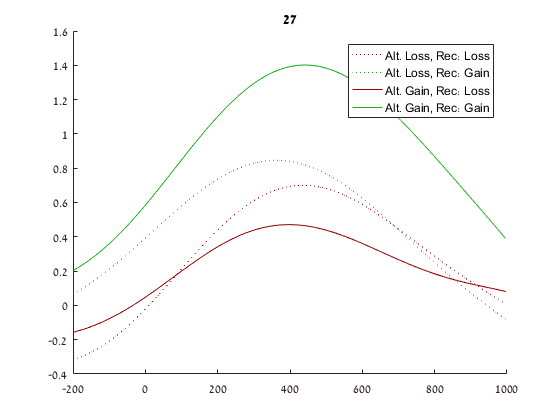

Comparing Theta Power - 4.5

show_4_erp(mean(squeeze(total_powers(freq_ind,:,:,:)),3), u, t)
title(fprintf('Comparing Theta Power - %.1f', freqs(freq_ind)))

Cluster 1: time points 231 to 307, t-sum = -140.723, p-value = 0.193181.


Cluster 1: time points 1 to 281, t-sum = -903.67, p-value = 0.00089991.


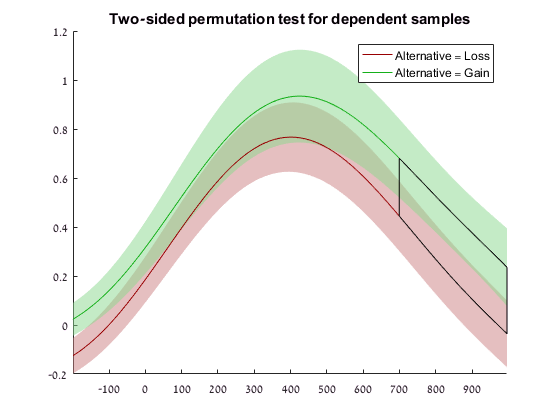

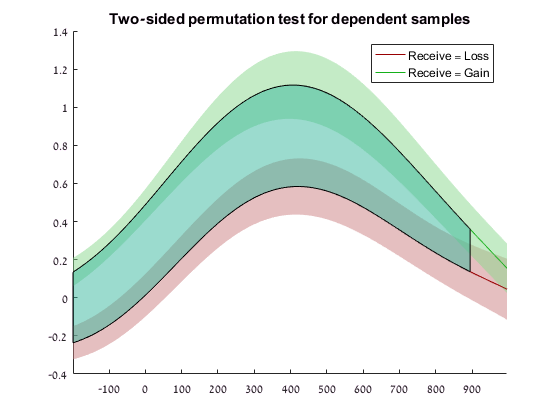


figure;
show_erp_alt_rec(squeeze(total_powers(freq_ind,:,:,:)), u, t)

p_thresh = 0.05;
n = 1e4;
freq_ind = 10;
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing freq power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing freq power %.2gHz - bin', freqs(freq_ind)))
freq_ind = 11;
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing freq power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing freq power %.2gHz - bin', freqs(freq_ind)))


p_thresh = 0.05;
n = 1e4;
freq_ind = 10;
compare_4_conditions(squeeze(sub_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing induced freq power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(sub_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing induced power %.2gHz - bin', freqs(freq_ind)))
freq_ind = 11;
compare_4_conditions(squeeze(sub_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing induced  power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(sub_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing induced  power %.2gHz - bin', freqs(freq_ind)))

# Delta

## comparing only Delta powers

delta_power_condition = zeros([length(times), max(condition_positions), length(results)]);
% theta_power_condition2 = theta_power_condition;

freq_min_d = 1;
freq_max_d = 3;
for subj_ind = 1:length(results)
    delta_power_subject = get_hilbert_power(results{subj_ind}.trials, freq_min_d, freq_max_d, SamplingInterval);
    bl_value = mean(mean(delta_power_subject(bl_range, :),2),1);
    
    for cond_ind = 1:size(delta_power_condition,2)
        delta_power_condition(:,cond_ind,subj_ind) = 10 * log10(mean(delta_power_subject(:,results{subj_ind}.condition_positions == cond_ind)./bl_value,2));
%         delta_power_condition2(:,cond_ind,subj_ind) = mean(10 * log10(delta_power_subject(:,results{subj_ind}.condition_positions == cond_ind)./bl_value),2);
    end
end

delta_erp_power_condition = [];
for subj_ind = 1:length(results)
    for cond_ind = 1:size(delta_power_condition,2)
        delta_erp_power_condition(:,cond_ind,subj_ind) = get_hilbert_power(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min_d, freq_max_d, SamplingInterval);
    end
end


p_thresh = 0.05;
n = 1e4;
compare_4_conditions(delta_power_condition, u, t, freqs, p_thresh, n, false, sprintf('comparing mean Delta (%.2g-%.2g)- mean', freq_min_d, freq_max_d))
compare_4_conditions(delta_power_condition, u, t, freqs, p_thresh, n, true, sprintf('comparing mean Delta (%.2g-%.2g)- bin', freq_min_d, freq_max_d))
% compare_4_conditions(theta_power_condition2, u, t, freqs, p_thresh, n, false, sprintf('comparing log-mean Delta (%.2g-%.2g)- mean', freq_min_d, freq_max_d))
% compare_4_conditions(theta_power_condition2, u, t, freqs, p_thresh, n, true, sprintf('comparing log-mean Delta (%.2g-%.2g)- bin', freq_min_d, freq_max_d))
compare_4_conditions(delta_erp_power_condition, u, t, freqs, p_thresh, n, false, sprintf('comparing ERP Delta (%.2g-%.2g)- mean', freq_min_d, freq_max_d))
compare_4_conditions(delta_erp_power_condition, u, t, freqs, p_thresh, n, true, sprintf('comparing ERP Delta (%.2g-%.2g)- bin', freq_min_d, freq_max_d))

## using wavelets

p_thresh = 0.05;
n = 1e4;
freq_ind = 2;
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing freq power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing freq power %.2gHz - bin', freqs(freq_ind)))
freq_ind = 3;
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, false, sprintf('comparing freq power %.2gHz - mean', freqs(freq_ind)))
compare_4_conditions(squeeze(total_powers(freq_ind,:,:,:)), u, t, freqs, p_thresh, n, true, sprintf('comparing freq power %.2gHz - bin', freqs(freq_ind)))


function show_erp(original_erps,left_ind,right_ind, u, t, condition_names)
show_perm_results(original_erps,left_ind,right_ind, u, t)
title(['comparing tsum; ' condition_names{left_ind} ':' condition_names{right_ind}])
end

function show_perm_powers(data, left_inds, right_inds, u, t, p_thresh, num_permutations, is_bin, freqs)

set_default('is_bin', false);
set_default('p_thresh', 0.05);
set_default('num_permutations', 1e4);

is2dData = ndims(data) == 4;

if left_inds<0
    left_inds = find(1:4 ~= -left_inds);
end
if right_inds<0
    right_inds = find(1:4 ~= -right_inds);
end

if is2dData
    trial_g_1 = squeeze(mean(data(:,u,left_inds, :),3));
    if right_inds ~= 0
        trial_g_2 = squeeze(mean(data(:,u,right_inds, :),3));
    end    
else
    trial_g_1 = squeeze(mean(data(u,left_inds, :), 2));
    if right_inds ~= 0
        trial_g_2 = squeeze(mean(data(u,right_inds, :), 2));
    end
end

if right_inds == 0
    trial_g_2 = 0
end

if ~is2dData && ~is_bin
    trial_g = trial_g_1;
    thresh_g = trial_g_2;
else
    trial_g = trial_g_1 - trial_g_2;
    
    if is_bin
        trial_g = 1*(trial_g>0);
        thresh_g = 0.5;
    else
        thresh_g = 0;
    end
end

% thresh_g = 0;
% if right_inds == 0
%     trial_g = trial_g_1;
% else
%     if is2dData
%         trial_g = trial_g_1 - trial_g_2;
%     else
%         trial_g = trial_g_1;
%         thresh_g = trial_g_2;
%     end
% end
%
% if is_bin
%     trial_g = 1*(trial_g-thresh_g>0);
%     thresh_g = 0.5;
% end

if is2dData
    permutest_2dplot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, true, t, freqs);
else
    permutest_plot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, t, false);
end

end

function compare_4_conditions(data,u,t,freqs,p_thresh, n,is_bin, title_fig)
figure;
subplot(2,2,1)
show_perm_powers(data, 3, 1, u, t, p_thresh, n, is_bin, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_powers(data, 4, 2, u, t, p_thresh, n, is_bin, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_powers(data, 1:2, 3:4, u, t, p_thresh, n, is_bin, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_powers(data, [1 3], [2 4], u, t, p_thresh, n, is_bin, freqs);
title 'll+gl:lg+gg'
title_subplots(title_fig)
end

function show_erp_alt_rec(data, u, t)
p_thresh = 0.05;
num_permutations = 1e4;
figure;
permutest_plot(squeeze(mean(data(u,1:2,:),2)),squeeze( mean(data(u,3:4,:),2)), true, p_thresh, num_permutations, true, inf, t, true, {rgb('blood red'), rgb('green')});
legend({'Alternative = Loss', 'Alternative = Gain'})
figure;
permutest_plot(squeeze(mean(data(u,[1,3],:),2)),squeeze( mean(data(u,[2,4],:),2)), true, p_thresh, num_permutations, true, inf, t, true, {rgb('blood red'), rgb('green')});
legend({'Receive = Loss', 'Receive = Gain'})
end


function show_4_erp(data,u,t)
figure;
hold on
plot(t,data(u,1), ':', 'color', rgb('blood red'))
plot(t,data(u,2), ':', 'color', rgb('green'))
plot(t,data(u,3), '-', 'color', rgb('blood red'))
plot(t,data(u,4), '-', 'color', rgb('green'))
legend({'Alt. Loss, Rec: Loss',
        'Alt. Loss, Rec: Gain',
        'Alt. Gain, Rec: Loss',
        'Alt. Gain, Rec: Gain'})
end
